# Part 9:  Problem set answers

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

## 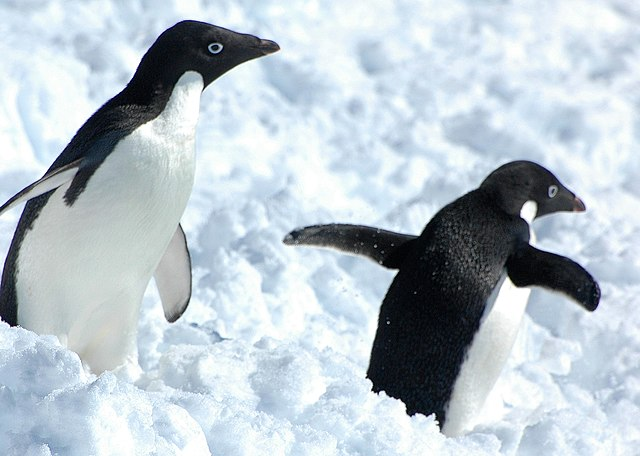

Adelie penguins plodding through [snow](https://commons.wikimedia.org/wiki/File:2007_Snow-Hill-Island_Luyten-De-Hauwere-Adelie-Penguin-20.jpg). 

## Load and set up necessary data: 

filename = "penguins.csv";
%penguins = readtable(filename);
penguins.species = categorical(penguins.species);
penguins.island = categorical(penguins.island);
penguins.sex = categorical(penguins.sex);
penguins1 = rmmissing(penguins);
chinstrap = penguins1(penguins1.species == "Chinstrap",:);
gentoo = penguins1(penguins1.species == "Gentoo",:); 
adelie = penguins1(penguins1.species == "Adelie",:);

## Problem 1:

Use  `scatter() to p`lot bill depth versus bill length (hint: `penguins1.bill_length_mm`) for all penguins. Don't forget to include labels! 

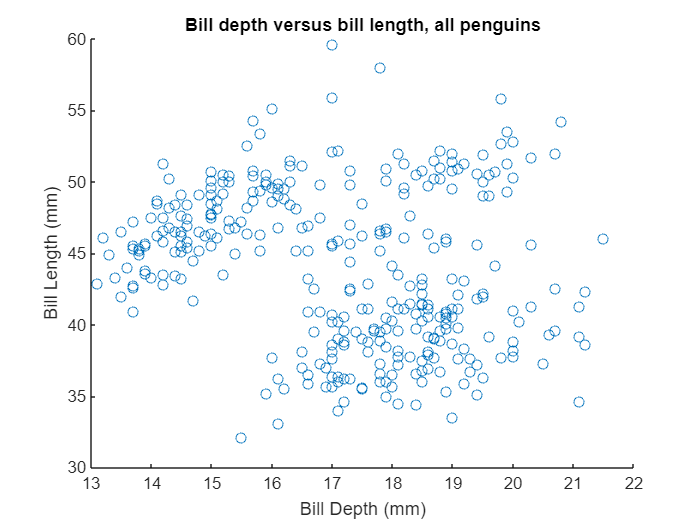

scatter(penguins1.bill_depth_mm, penguins1.bill_length_mm)
xlabel("Bill Depth (mm)")
ylabel("Bill Length (mm)")
title("Bill depth versus bill length, all penguins")

  **Bonus:** as we did in the biosciences data module, use `gscatter()` to break this plot up by species. 

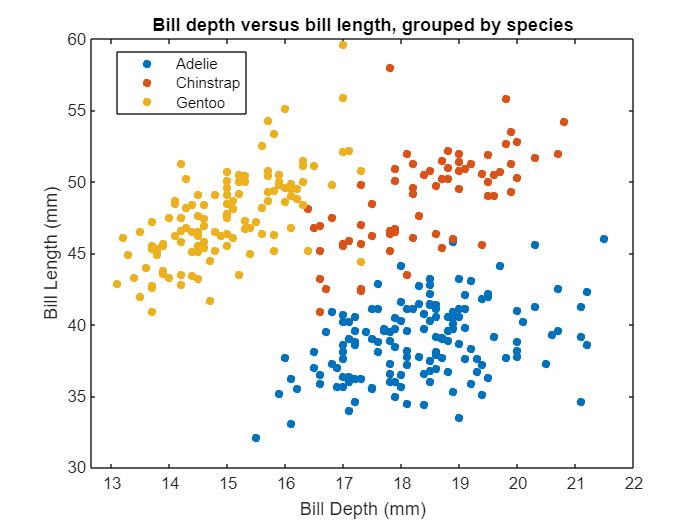

gscatter(penguins1.bill_depth_mm, penguins1.bill_length_mm, penguins1.species)
xlabel("Bill Depth (mm)")
ylabel("Bill Length (mm)")
title("Bill depth versus bill length, grouped by species")

## Problem 2: 

Create a box plot of bill length for all species of penguins (label the x and y axes!)

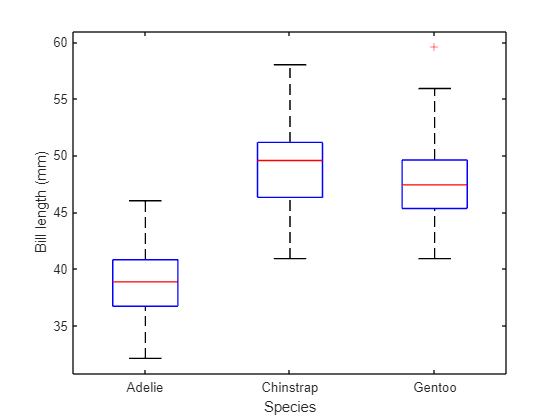

boxplot(penguins1.bill_length_mm, penguins1.species)
xlabel("Species")
ylabel("Bill length (mm)")

Create a box plot of bill depth for all species of penguins. 

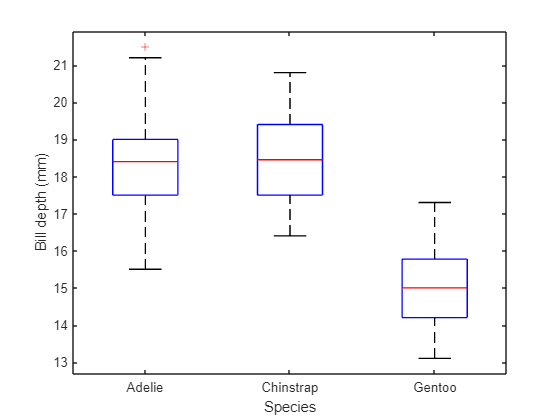

boxplot(penguins1.bill_depth_mm, penguins1.species)
xlabel("Species")
ylabel("Bill depth (mm)")

 Based on these box plots (you can also look at the scatter plot from Problem 1), make some observations about how bill length and bill depth vary by species. 

Students can make any reasonable observations such as  "Gentoo bill depth is likely significantly different from Chinstrap bill depth, but Adelie and Chinstrap bill depth may be indistinguishable". 

If students compare the box plots to the scatter plot, they may point out that Gentoos have the lowest bill depth distribution on the boxplot, which leads to their distribution on the scatter plot being skewed left. Chinstrap and Gentoo penguins have similar bill length distributions, which leads to them being relatively closely clustered on the y-axis.

## Problem 3: 

Based on the observations you just made, write down two hypotheses about how bill length or bill depth differs (or doesn't!) between species. You can come up with any hypotheses you want, as long as you can test them! 

Any hypotheses are welcome, whether they are proven or not. I chose H1: "Gentoo penguins have a significantly lower bill depth size than Chinstrap penguins" and H2: "Adelie penguins have a significantly shorter bill length than Chinstrap penguins". 

 For hypothesis 1, jot down the null and alternate hypotheses. 

Use` ttest2()` to test your hypothesis: 

[h1, p1] = ttest2(gentoo.bill_depth_mm, chinstrap.bill_depth_mm) 

h1 = 1

p1 = 1.7885e-52

 Write a sentence or two about what the test decision (h) and p-value (p) mean. Was your hypothesis proven or disproven? 

Repeat the 3 steps above for your second hypothesis: 

[h2, p2] = ttest2(adelie.bill_length_mm, chinstrap.bill_length_mm)

h2 = 1

p2 = 3.9882e-61

In this case, hypothesis 1 is proven (null hypothesis is rejected). The null is also rejected for hypothesis 2, and this hypothesis is also proven. 

[*Return to problem set*](matlab: edit S8_Problem_Set.mlx)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)